# LSTM

## Creating LSTM Model

numChannels = 1;
numObservations = length(random_data_matrix);

idx = 1:length(random_data_matrix);
idxTrain = idx(1:0.9*size(idx,2));
idxTest = idx(0.9*size(idx,2):size(idx,2));

dataTrain = random_data_matrix_Cell(idxTrain);
dataTest = random_data_matrix_Cell(idxTest);

for n = 1:numel(dataTrain)
    X = dataTrain{n};
    XTrain{n} = X(:,1:end-1);
    TTrain{n} = X(:,2:end);
end

muX = mean(cat(2,XTrain{:}),2);
sigmaX = std(cat(2,XTrain{:}),0,2);

muT = mean(cat(2,TTrain{:}),2);
sigmaT = std(cat(2,TTrain{:}),0,2);



for n = 1:numel(XTrain)
    XTrain{n} = (XTrain{n} - muX) ./ sigmaX;
    TTrain{n} = (TTrain{n} - muT) ./ sigmaT;
end


## prepare data for regresion

total_data_matrix_for_regresion = (total_data_matrix - muX) ./ sigmaX;

layers = [
    sequenceInputLayer(numChannels)
    lstmLayer(128)
    fullyConnectedLayer(numChannels)
    regressionLayer];

%for Tom 
% options = trainingOptions("adam",...
%     'MaxEpochs', 200, ...
%     'SequencePaddingDirection', "left", ...
%     'Shuffle', "every-epoch", ...
%     'Plots', "training-progress", ...
%     'Verbose', 0)

% for Lidor
options = trainingOptions("adam", ...
    MaxEpochs=200, ...
    SequencePaddingDirection="left", ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=0);

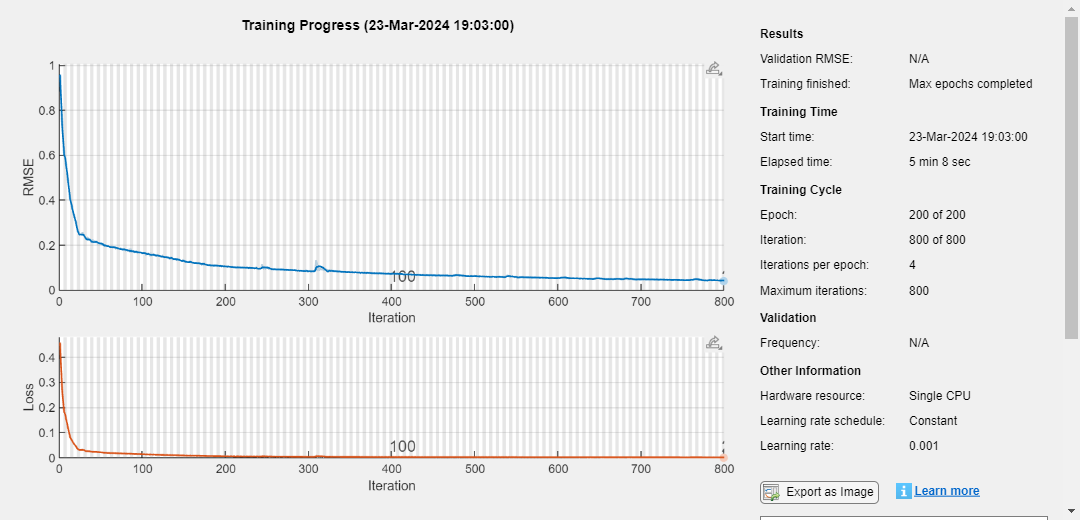

net = trainNetwork(XTrain,TTrain,layers,options);

for n = 1:size(dataTest,1)
    X = dataTest{n};
    XTest{n} = (X(:,1:end-1) - muX) ./ sigmaX;
    TTest{n} = (X(:,2:end) - muT) ./ sigmaT;
end

YTest = predict(net,XTest,SequencePaddingDirection="left");

for i = 1:size(YTest,1)
    rmse(i) = sqrt(mean((YTest{i} - TTest{i}).^2,"all"));
end

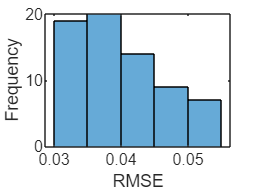

figure
histogram(rmse)
xlabel("RMSE")
ylabel("Frequency")

mean(rmse)

ans = single
0.0401

## 2023 Data for Estimation

% mu2023 = mean(cat(2,data_matrix_2023_Cell{:}),2);
% sigma2023 = std(cat(2,data_matrix_2023_Cell{:}),0,2);
% 
% data_matrix_2023 = (data_matrix_2023 - mu2023) ./ sigma2023;


offset = 15;

Predictions_LSTM_2023 = zeros([],[]);

%offset = 1;

for idx = 1 : size(data_matrix_2023,1)
    day_to_predict_in_2023 = data_matrix_2023_NORMALIZED(idx,:);
    net_currently_updated = resetState(net);
    
    [net_currently_updated,~] = predictAndUpdateState(net_currently_updated,day_to_predict_in_2023(:,1:offset));

    numTimeSteps = size(day_to_predict_in_2023,2);
    numPredictionTimeSteps = numTimeSteps - offset;
    Y = zeros(numChannels,numPredictionTimeSteps);
    
    for t = 1:numPredictionTimeSteps
        day_to_predict_in_2023_t = day_to_predict_in_2023(:,offset+t);
        [net_currently_updated,Y(:,t)] = predictAndUpdateState(net_currently_updated,day_to_predict_in_2023_t);
    end

    Predictions_LSTM_2023(idx,:) = Y;
end

## Plot for Example Prediction Vs. Real

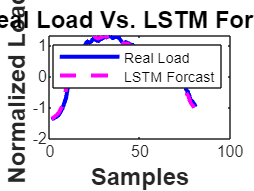


offset = 15;
chosen = 57;
t_lstm = 1:96-offset;
figure;
plot(t_lstm,data_matrix_2023_NORMALIZED(chosen,offset+1:end),"b","LineWidth",2);
hold on
plot(t_lstm,Predictions_LSTM_2023(chosen,:),"m--","LineWidth",2);

title('Real Load Vs. LSTM Forcast','FontSize',12,'FontWeight','bold');
legend('Real Load','LSTM Forcast');
xlabel('Samples','FontSize',12,'FontWeight','bold')
ylabel('Normalized Load','FontSize',12,'FontWeight','bold');

## Plot for Example Prediction Vs. Real

% figure
% t = tiledlayout(numChannels,1);
% title(t,"Real Load Vs. LSTM Forecasting",'FontSize',12,'FontWeight','bold')
% 
% idx_current_prediction = 85;
% day_to_predict_in_2023 = data_matrix_2023_NORMALIZED(idx_current_prediction,:);
% Y = Predictions_LSTM_2023(idx_current_prediction,:);
% 
% for i = 1:numChannels
%     nexttile
%     plot(day_to_predict_in_2023(i,:),'LineWidth',2.5)
%     hold on
%     plot(offset:numTimeSteps,[day_to_predict_in_2023(i,offset) Y(i,:)],'m--','LineWidth',2.5)
%     ylabel("Channel " + i)
% end
% 
% xlabel("Samples",'FontSize',12,'FontWeight','bold')
% ylabel("Normalized Load",'FontSize',12,'FontWeight','bold');
% nexttile(1)
% legend(["Real Load" "LSTM Forecast"])


## 'Shortest Path' on Prediction and Real G

Shorters_on_real_G_LSTM_2023_E5 = zeros([],[]);
Shortest_on_pred_LSTM_2023_E5 = zeros([],[]);

Shorters_on_real_G_LSTM_2023_E10 = zeros([],[]);
Shortest_on_pred_LSTM_2023_E10 = zeros([],[]);

Shorters_on_real_G_LSTM_2023_E20 = zeros([],[]);
Shortest_on_pred_LSTM_2023_E20 = zeros([],[]);

Shorters_on_real_G_LSTM_2023_E30 = zeros([],[]);
Shortest_on_pred_LSTM_2023_E30 = zeros([],[]);

Shorters_on_real_G_LSTM_2023_E40 = zeros([],[]);
Shortest_on_pred_LSTM_2023_E40 = zeros([],[]);

Shorters_on_real_G_LSTM_2023_E100 = zeros([],[]);
Shortest_on_pred_LSTM_2023_E100 = zeros([],[]);


%offset = 15;

for i = 1:size(energy_sizes_percentage,2)
    print = 0;
    i
    switch i

        case 1
            E_max = Storage_size(1);
            for idx = 1 : size(data_matrix_2023,1)
                day_to_predict_in_2023 = data_matrix_2023_NORMALIZED(idx,:);
                Shortest_on_pred_LSTM_2023_E5(idx,:) = YES_shortest_on_prediction_fnc(Predictions_LSTM_2023(idx,:),sigma2023,mu2023,E_max,print);
                Shorters_on_real_G_LSTM_2023_E5(idx,:) = YES_shortest_on_prediction_fnc(day_to_predict_in_2023(offset + 1 : end),sigma2023,mu2023,E_max,print);
            end

        case 2
            E_max = Storage_size(2);
            for idx = 1 : size(data_matrix_2023,1)
            day_to_predict_in_2023 = data_matrix_2023_NORMALIZED(idx,:);
            Shortest_on_pred_LSTM_2023_E10(idx,:) = YES_shortest_on_prediction_fnc(Predictions_LSTM_2023(idx,:),sigma2023,mu2023,E_max,print);
            Shorters_on_real_G_LSTM_2023_E10(idx,:) = YES_shortest_on_prediction_fnc(day_to_predict_in_2023(offset + 1 : end),sigma2023,mu2023,E_max,print);
            end

        case 3
            E_max = Storage_size(3);
            for idx = 1 : size(data_matrix_2023,1)
            day_to_predict_in_2023 = data_matrix_2023_NORMALIZED(idx,:);
            Shortest_on_pred_LSTM_2023_E20(idx,:) = YES_shortest_on_prediction_fnc(Predictions_LSTM_2023(idx,:),sigma2023,mu2023,E_max,print);
            Shorters_on_real_G_LSTM_2023_E20(idx,:) = YES_shortest_on_prediction_fnc(day_to_predict_in_2023(offset + 1 : end),sigma2023,mu2023,E_max,print);
            end

        case 4
            E_max = Storage_size(4);
            for idx = 1 : size(data_matrix_2023,1)
            day_to_predict_in_2023 = data_matrix_2023_NORMALIZED(idx,:);
            Shortest_on_pred_LSTM_2023_E30(idx,:) = YES_shortest_on_prediction_fnc(Predictions_LSTM_2023(idx,:),sigma2023,mu2023,E_max,print);
            Shorters_on_real_G_LSTM_2023_E30(idx,:) = YES_shortest_on_prediction_fnc(day_to_predict_in_2023(offset + 1 : end),sigma2023,mu2023,E_max,print);
            end

        case 5
            E_max = Storage_size(5);
            for idx = 1 : size(data_matrix_2023,1)
            day_to_predict_in_2023 = data_matrix_2023_NORMALIZED(idx,:);
            Shortest_on_pred_LSTM_2023_E40(idx,:) = YES_shortest_on_prediction_fnc(Predictions_LSTM_2023(idx,:),sigma2023,mu2023,E_max,print);
            Shorters_on_real_G_LSTM_2023_E40(idx,:) = YES_shortest_on_prediction_fnc(day_to_predict_in_2023(offset + 1 : end),sigma2023,mu2023,E_max,print);
            end
        case 6
            E_max = Storage_size(6);
            for idx = 1 : size(data_matrix_2023,1)
            day_to_predict_in_2023 = data_matrix_2023_NORMALIZED(idx,:);
            Shortest_on_pred_LSTM_2023_E100(idx,:) = YES_shortest_on_prediction_fnc(Predictions_LSTM_2023(idx,:),sigma2023,mu2023,E_max,print);
            Shorters_on_real_G_LSTM_2023_E100(idx,:) = YES_shortest_on_prediction_fnc(day_to_predict_in_2023(offset + 1 : end),sigma2023,mu2023,E_max,print);
            end
    end

    
end


i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

## Plot for Example 'Shortest Path' on Prediction Vs. Real

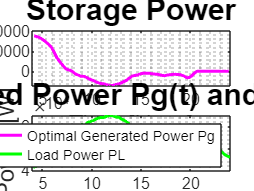

print = 1;
E_max = Storage_size(6);
YES_shortest_on_prediction_fnc(day_to_predict_in_2023(offset+1:end),sigma2023,mu2023,E_max,print);

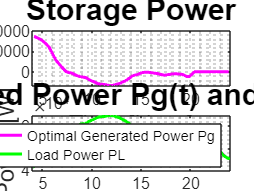

YES_shortest_on_prediction_fnc(Predictions_LSTM_2023(idx,:),sigma2023,mu2023,E_max,print);